## Aim 1 heatmap of all neurons vs odors, 

nwb = nwbRead('Neural signal project/sub-7_ses-20200213T113524_ophys.nwb');

ophys = get(nwb.processing, 'ophys');
fluorescence = get(ophys.nwbdatainterface, 'Fluorescence');

roi_response = get(fluorescence.roiresponseseries, 'Plane_0');
dff = roi_response.data.load();              
timestamps = roi_response.timestamps.load(); 

odor = get(nwb.stimulus_presentation, 'odor');
stim_timestamps = odor.timestamps.load();  
stim_labels = odor.data.load();            

% 確保 stim_labels 與 stim_timestamps 為 column vector
stim_labels = stim_labels(:);
stim_timestamps = stim_timestamps(:);

% 找出氣味變化點（onset）
odor_onset_idx = find([true; diff(stim_labels) ~= 0]);

% 抓出 onset 對應時間與氣味 label
odor_onset_times = stim_timestamps(odor_onset_idx);
odor_onset_labels = stim_labels(odor_onset_idx);

% 篩掉無效 label（背景或 NaN）
valid_mask = ~isnan(odor_onset_labels) & odor_onset_labels >= 0;
odor_onset_times = odor_onset_times(valid_mask);
odor_onset_labels = odor_onset_labels(valid_mask);

% 👉 可選：過濾太短間隔（如果你發現某些氣味持續時間太短）
% min_interval = 3; % 單位秒
% keep = [true; diff(odor_onset_times) > min_interval];
% odor_onset_times = odor_onset_times(keep);
% odor_onset_labels = odor_onset_labels(keep);

% 🔍 額外分析：找出反應強且穩定的 neuron × odor 組合
high_response_threshold = 0.1;  % 反應強度 ΔF/F 閾值
max_cv_threshold = 0.7;         % 變異係數（穩定性）閾值

% 找出強且穩定的 neuron-odor 組合
results = [];

for neuron = 1:n_cells
    for odor = 1:n_odors
        trial_idx = find(odor_onset_labels == odor);
        trials = trial_responses(neuron, trial_idx);

        if numel(trials) < 3
            continue;
        end

        mean_dff = mean(trials, 'omitnan');
        std_dff = std(trials, 'omitnan');
        cv_dff = std_dff / (abs(mean_dff) + 1e-6);  % 防止除 0

        if mean_dff > high_response_threshold && cv_dff < max_cv_threshold
            results = [results; neuron, odor, mean_dff, std_dff, cv_dff];
        end
    end
end

% ✅ 確保即使為空，也能建表格
if isempty(results)
    results = nan(0,5);  % 建立空表格：0 行 5 欄
end

T = array2table(results, ...
    'VariableNames', {'Neuron', 'Odor', 'Mean_dF_F', 'Std_dF_F', 'CV_dF_F'});

disp('✅ Neuron-Odor combinations with strong and stable responses:');

✅ Neuron-Odor combinations with strong and stable responses:


disp(T);

    Neuron    Odor    Mean_dF_F    Std_dF_F    CV_dF_F
    ______    ____    _________    ________    _______

       2       2       0.31593       0.1815    0.57451
      66       2       0.14304      0.08355    0.58412
      70       1       0.17994      0.12059    0.67015
      70       2       0.10335     0.053338     0.5161



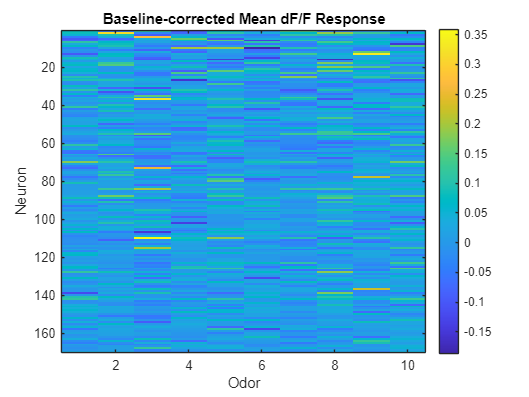

resp_window = [0, 2];         % 分析視窗（刺激後）
baseline_window = [-1, 0];    % 基線視窗（刺激前）

fps = 1 / median(diff(timestamps));
resp_frames = round(resp_window * fps);
base_frames = round(baseline_window * fps);

n_cells = size(dff, 1);
n_odors = 10;
trial_responses = zeros(n_cells, length(odor_onset_times));

for i = 1:length(odor_onset_times)
    t0 = odor_onset_times(i);
    [~, onset_idx] = min(abs(timestamps - t0));
    
    base_idx = onset_idx + base_frames(1):onset_idx + base_frames(2);
    resp_idx = onset_idx + resp_frames(1):onset_idx + resp_frames(2);

    if min(base_idx) < 1 || max(resp_idx) > size(dff, 2)
        trial_responses(:, i) = NaN;
        continue;
    end

    F0 = mean(dff(:, base_idx), 2);
    F_resp = mean(dff(:, resp_idx), 2);
    dff_trial = (F_resp - F0) ./ F0;

    trial_responses(:, i) = dff_trial;
end

% 平均每個氣味反應
mean_responses = zeros(n_cells, n_odors);
for odor = 1:n_odors
    idx = find(odor_onset_labels == odor);
    mean_responses(:, odor) = mean(trial_responses(:, idx), 2, 'omitnan');
end

% heatmap
figure;
imagesc(mean_responses);
xlabel('Odor'); ylabel('Neuron');
title('Baseline-corrected Mean dF/F Response');
colorbar;

% 🎯 取出 max odor response per neuron，排序後取前10
max_response_per_neuron = max(mean_responses, [], 2);  % 每個 neuron 的最大反應
[~, sorted_idx] = sort(max_response_per_neuron, 'descend');
top_n = 10;
top_neuron_idx = sorted_idx(1:min(top_n, length(sorted_idx)));  % 防止少於10個

% 📊 擷取 top 10 neuron 的 mean_responses
top10_responses = mean_responses(top_neuron_idx, :);

% 🎨 畫 heatmap
figure;
imagesc(top10_responses);
xlabel('Odor');
ylabel('Neuron (Top 10)');
yticks(1:length(top_neuron_idx));
yticklabels(top_neuron_idx);  % 顯示 neuron 編號
title('Top 10 Neurons with Strongest Odor Responses');
colorbar;
colormap('hot');

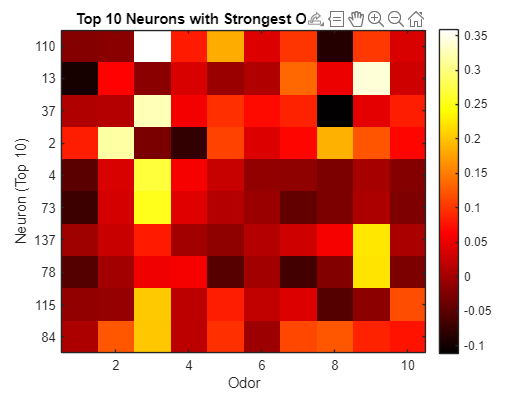

% 🎯 取出 max odor response per neuron，排序後取前10
max_response_per_neuron = max(mean_responses, [], 2);  % 每個 neuron 的最大反應
[~, sorted_idx] = sort(max_response_per_neuron, 'descend');
top_n = 10;
top_neuron_idx = sorted_idx(1:min(top_n, length(sorted_idx)));  % 防止少於10個

% 📊 擷取 top 10 neuron 的 mean_responses
top10_responses = mean_responses(top_neuron_idx, :);

% 🎨 畫 heatmap
figure;
imagesc(top10_responses);
xlabel('Odor');
ylabel('Neuron (Top 10)');
yticks(1:length(top_neuron_idx));
yticklabels(top_neuron_idx);  % 顯示 neuron 編號
title('Top 10 Neurons with Strongest Odor Responses');
colorbar;
colormap('hot');

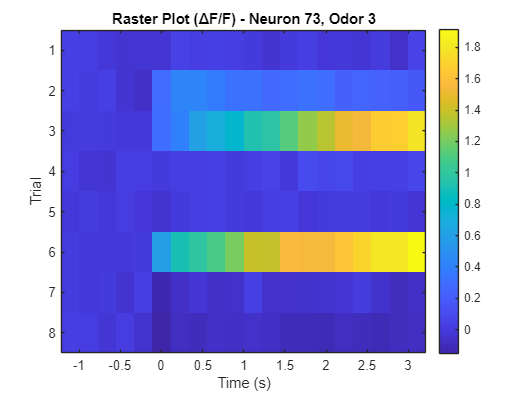

neuron_id = 73;    
target_odor = 3;  
window = [-1, 3];  % -1秒到+3秒

fps = 1 / median(diff(timestamps));
win_frames = round(window(1) * fps):round(window(2) * fps);
t_axis = win_frames / fps;

trial_idx = find(odor_onset_labels == target_odor);
n_trials = length(trial_idx);
raster_data = zeros(n_trials, length(win_frames));

for i = 1:n_trials
    t0 = odor_onset_times(trial_idx(i));
    [~, onset_idx] = min(abs(timestamps - t0));
    idx = onset_idx + win_frames;

    if min(idx) < 1 || max(idx) > length(timestamps)
        raster_data(i, :) = NaN;
        continue;
    end

    % ✅ baseline normalization
    baseline_idx = idx(t_axis < 0);  % 用刺激前的時間作為 baseline
    F0 = mean(dff(neuron_id, baseline_idx), 'omitnan');
    raster_data(i, :) = (dff(neuron_id, idx) - F0) / F0;
end

% 🔍 Raster plot（每一列是一個 trial 的 ΔF/F）
figure;
imagesc(t_axis, 1:n_trials, raster_data);
xlabel('Time (s)'); ylabel('Trial');
title(sprintf('Raster Plot (ΔF/F) - Neuron %d, Odor %d', neuron_id, target_odor));
colorbar;

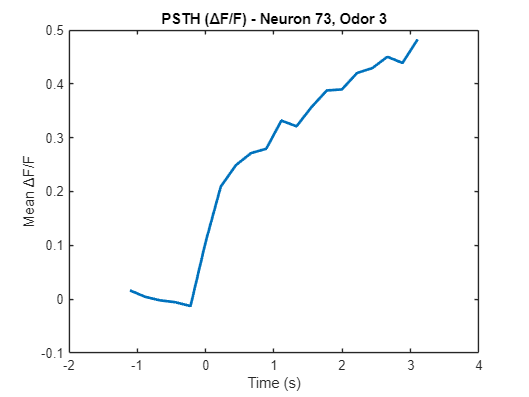


% 📊 PSTH（平均 ΔF/F trace across trials）
mean_trace = nanmean(raster_data, 1);
figure;
plot(t_axis, mean_trace, 'LineWidth', 2);
xlabel('Time (s)'); ylabel('Mean ΔF/F');
title(sprintf('PSTH (ΔF/F) - Neuron %d, Odor %d', neuron_id, target_odor));

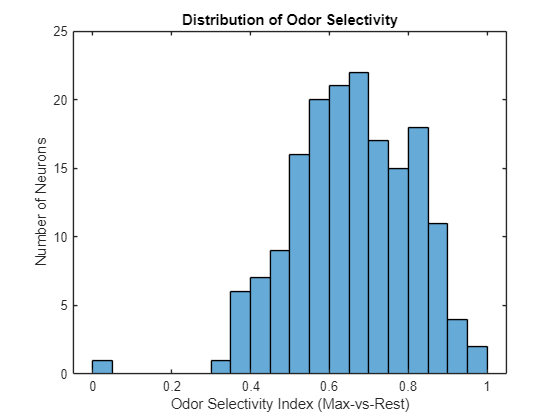

% ✅ 1. 計算 OSI（Max-vs-Rest 版本）
n_cells = size(mean_responses, 1);
OSI = zeros(n_cells, 1);

for n = 1:n_cells
    responses = mean_responses(n, :);
    
    % 修正：將負值設為0，避免 denominator 太小或出現錯誤比值
    responses(responses < 0) = 0;

    [r_max, max_idx] = max(responses);
    rest = responses;
    rest(max_idx) = [];
    r_mean_others = mean(rest, 'omitnan');

    OSI(n) = (r_max - r_mean_others) / (r_max + r_mean_others + 1e-6);  % 防除 0
end


% ✅ 2. 畫 OSI histogram
figure;
histogram(OSI, 20);
xlabel('Odor Selectivity Index (Max-vs-Rest)');
ylabel('Number of Neurons');
title('Distribution of Odor Selectivity');


% ✅ 3. 建立 OSI 表格（排序找前10名）
[sorted_osi, sorted_idx] = sort(OSI, 'descend');
top_n = 10;
top_neuron_idx = sorted_idx(1:min(top_n, length(sorted_idx)));
top_osi_values = sorted_osi(1:min(top_n, length(sorted_idx)));

OSI_table = table(top_neuron_idx, top_osi_values, ...
    'VariableNames', {'Neuron', 'Max_vs_Rest_OSI'});
disp('🔍 Top OSI Neurons (Max-vs-Rest):');

🔍 Top OSI Neurons (Max-vs-Rest):


disp(OSI_table);

    Neuron    Max_vs_Rest_OSI
    ______    _______________

      11          0.99992    
      34          0.95018    
      29          0.92446    
      73          0.91807    
      56          0.91391    
       4          0.90308    
      78          0.89337    
     119          0.88112    
     113          0.87783    
      59          0.87556    



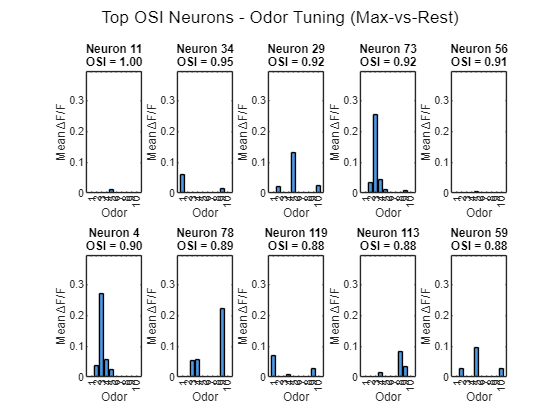


% ✅ 4. 畫出 top OSI neuron 的 tuning curves
figure;
for i = 1:length(top_neuron_idx)
    subplot(2, ceil(top_n/2), i);
    neuron_id = top_neuron_idx(i);
    bar(mean_responses(neuron_id, :), 'FaceColor', [0.3 0.6 0.9]);
    title(sprintf('Neuron %d\nOSI = %.2f', neuron_id, OSI(neuron_id)));
    xlabel('Odor'); ylabel('Mean ΔF/F');
    ylim([0 max(mean_responses(:))*1.1]);
end
sgtitle('Top OSI Neurons - Odor Tuning (Max-vs-Rest)');

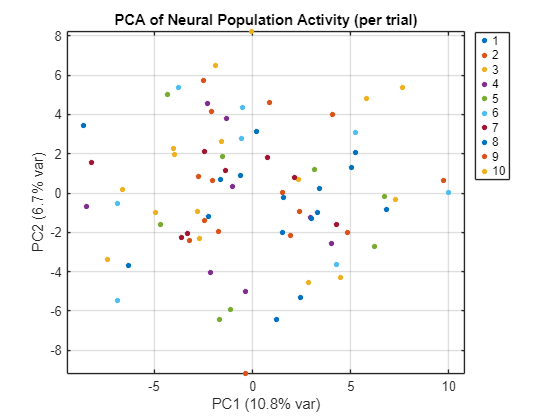

% --------------------------------------------
% 🎯 PCA 降維分析 - Aim 3
% --------------------------------------------

% 準備資料：每一筆 trial 是一個樣本
X = trial_responses';              % (n_trials × n_neurons)
Y = odor_onset_labels(:);         % 氣味標籤 (n_trials × 1)

% 移除包含 NaN 的 trial
valid_trials = all(~isnan(X), 2);
X_clean = X(valid_trials, :);
Y_clean = Y(valid_trials);

% Z-score normalization（每個 neuron mean=0, std=1）
X_norm = zscore(X_clean);

% PCA 降維
[coeff, score, ~, ~, explained] = pca(X_norm);

% --------------------------------------------
% 📊 繪製前兩主成分
% --------------------------------------------
figure;
gscatter(score(:,1), score(:,2), Y_clean, lines(10), '.', 12);
xlabel(sprintf('PC1 (%.1f%% var)', explained(1)));
ylabel(sprintf('PC2 (%.1f%% var)', explained(2)));
title('PCA of Neural Population Activity (per trial)');
legend('Location', 'bestoutside');
axis equal;
grid on;